Create a function to solve and plot the system.

Run code using ode45

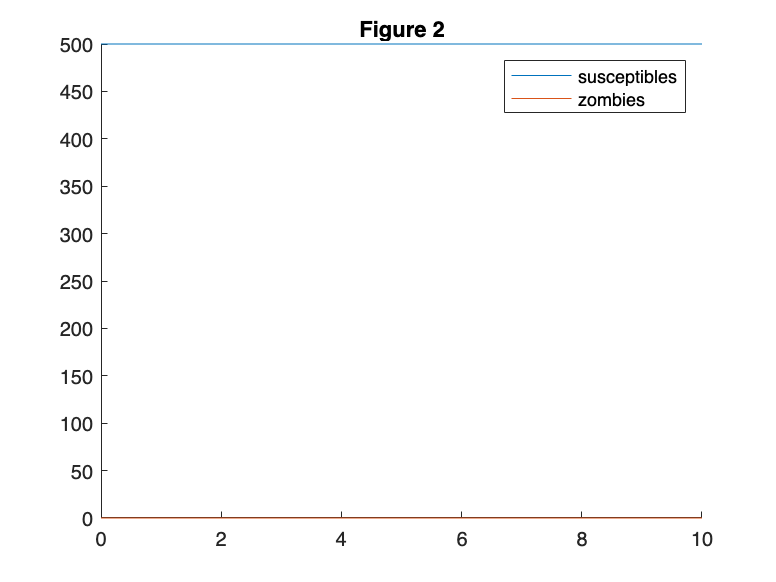

tRange = [0 10];
Y0 = [500; 0; 0];
[tSol, YSol] = ode45(@zombies, tRange, Y0);
close all;
hold on;
plot(tSol, YSol(:,1))
plot(tSol, YSol(:,2))
title("Figure 2")
hold off
legend('susceptibles', "zombies")

figure()

Function Declaration

function dYdt = zombies(~, Y)
p = 0;  % assume birth rate and background rate same
b = 0.0095;  % rate of new zombie
z = 0.0001;  % rate of removed becoming zombie
a = 0.005;  % rate of destroying zombie
d = 0;  % see p

S = Y(1);
Z = Y(2);
R = Y(3);

dSdt = p - b*S*Z - d*S;
dZdt = b*S*Z + z*R - a*S*Z;
dRdt = d*S + a*S*Z - z*R;

dYdt = [dSdt; dZdt; dRdt];
end